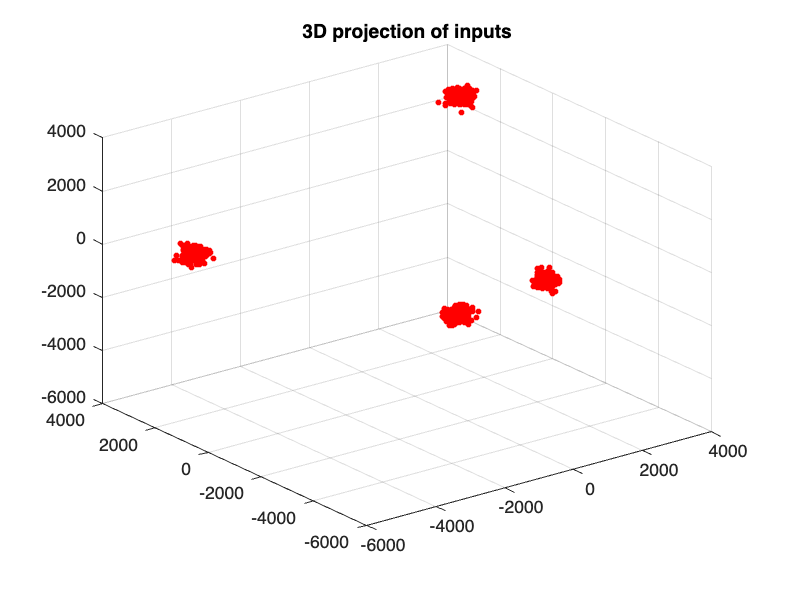

clear
format shortG
SetRNG(111);
% generate input data
k = 4;
dim = 100;
mu_range = [-1000 1000];
%mu_range = [0 2000];
sigma = 100;
split_num = 2;
[center1,mu_mat] = subcluster_centroid(k,dim,split_num,mu_range,sigma); 
means = [];

center = mu_mat;

% data generation with the given centroids
dim = 100;
num = 200;
sigma = 150;
[inputs,c] = subcluster_simulate(center,dim,num,sigma);


% noise = normrnd(1000, 20, 200,100);
% inputs = [inputs+noise;inputs-noise];
inputs = inputs - mean(inputs);
data = inputs';

% clear
% warning("off")
% load ('mnist.mat')
% num = 3000;
% colormap(gray(256))
% images = rescale(test.images(:,:,:),0,255);
% inputs_ori = reshape(images,784,10000)';
% %inputs_ori = inputs_ori(1:num,:);
% inputs = inputs_ori - mean(inputs_ori);
% data = inputs';
% dim = 784;



% pca on input data
coeff = pca(inputs);
Z=inputs*coeff(:,1:3);
figure;hold on
view(3);
plot3(Z(:,1),Z(:,2),Z(:,3),'r.','MarkerSize',10)
title('3D projection of inputs');
%legend('inputs','layer1 centroids','layer2 centroids','layer3 centroids','Location','NW')
grid on 
hold off

% generate synaptic weights
SetRNG(111);
n_src = dim;
n_dst = 50;
n_per_src = 20;
synaptic_weights_mat = randn(n_src,n_dst);
[srcIdx,dstIdx] = ConnectHypergeometric(n_dst, n_src, n_per_src);
index = [srcIdx;dstIdx];
for i = 1:n_dst;
    nonzero_idx = index(2,find(index(1,:) == i));
    zero_idx = setdiff(1:n_src,nonzero_idx);
    synaptic_weights_mat(zero_idx,i) = 0;
end
cells = synaptic_weights_mat; %original


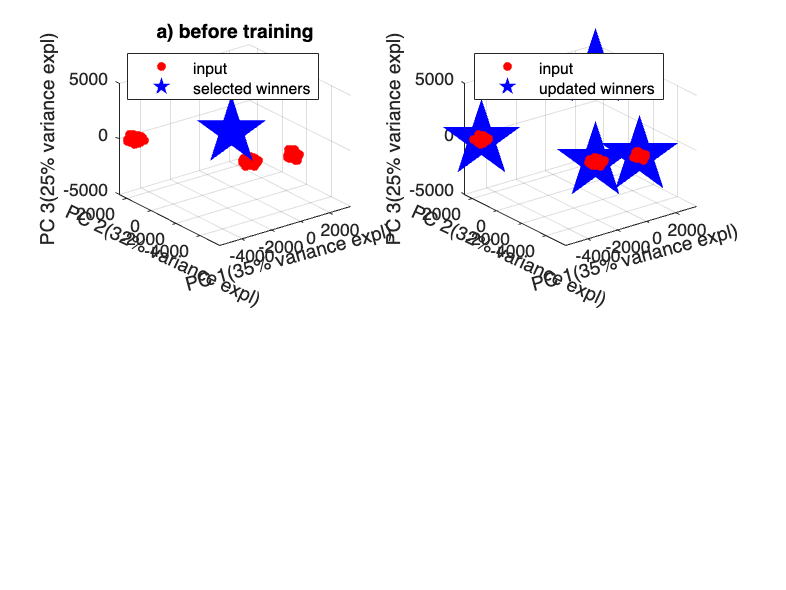

% cycle 1, find the cluster winners
ori_cycle1_cells = cells;
cycle1_cells = normc(cells);
cycle1_cells_iter = normc(cells);
norm_inputs = normr(inputs);
epoch = 60;
% the dot product needs normalization while the updating does not, so we
% have cycle1_cells and cycle1_cells_iter

for k = 1:epoch;
    cycle1_winners = [];
    sampled_data = data(:, randperm(size(data, 2)));
    winner_len_mat = [];
    winner_average = zeros(dim,1,n_dst);
    for col = 1:size(sampled_data,2); % loop over all inputs
        lr = 0.001;
        input1 = sampled_data(:,col);% each input
        len_input = norm(input1);
        input1 = normc(input1);
        winner_per_cycle = [];
        product = input1'*cycle1_cells; % the dot products of the input and all cells
        winning_value = max(product); % max dot product value
        winning_idx = find(product == winning_value); % index(indices) of winning cell(s)
        winning_cell = cycle1_cells(:,winning_idx); % the winning cell set, which may contain more than one winning cell
        % loop over each winning cell in the set, in case of tied winners,
        % which may not happen
        updated_winningset = []; % in case of tied winners
        for cell_idx = winning_idx;
            winner = cycle1_cells_iter(:,cell_idx);
            cycle1_winners = [cycle1_winners;cell_idx];
            update_winner_ori = winner+(input1-winner)*lr; %update_winner_ori is NOT norm
            winner_average(:,:,cell_idx) = update_winner_ori + winner_average(:,:,cell_idx);
            len_update_winner = norm(update_winner_ori);
            update_winner = update_winner_ori/len_update_winner;
            updated_winningset = [updated_winningset;update_winner];
            winner_len_mat = [winner_len_mat;[cell_idx,len_input]];           
            cycle1_cells(:,cell_idx) = update_winner; 
            cycle1_cells_iter(:,cell_idx) = update_winner_ori; 
        end  
    end
    
    % if (k > epoch*0.5) & (k <= epoch-1);
    %     [~,idx] = max(norm_inputs*cycle1_cells(:,cycle1_winners),[],2);
    %     cluster_assign_cycle = cycle1_winners(idx);
    %     for sub_winner_id = 1:length(cycle1_winners)
    %         sub_winner = cycle1_winners(sub_winner_id);
    %         input_idx = find(cluster_assign_cycle == sub_winner);
    %         cycle1_cells_iter(:,sub_winner) = cycle1_cells_iter(:,sub_winner)+(mean(norm_inputs(input_idx,:))'-cycle1_cells_iter(:,sub_winner))*lr;
    %     end
    % end
end
[~,~,ix] = unique(cycle1_winners,"stable");
winner_stats = [unique(cycle1_winners,"stable"),accumarray(ix,1)];

for i = 1:size(winner_stats,1);
winner_average(:,:,winner_stats(i,1)) = winner_average(:,:,winner_stats(i,1))./winner_stats(i,2);
cycle1_cells(:,winner_stats(i,1)) = winner_average(:,:,winner_stats(i,1)); 
end

% each input wins which?
cycle1_winner=cycle1_winners;
cycle1_winners = unique(cycle1_winners,"stable");
[~,idx_1] = max(normr(inputs)*cycle1_cells(:,cycle1_winners),[],2);
cycle1_winners = cycle1_winners(unique(idx_1,"stable")); 


for c = cycle1_winners';
    each_input = winner_len_mat(winner_len_mat(:,1)== c,2);
    ori_cycle1_cells(:,c) = cycle1_cells(:,c)*mean(each_input);
end
cycle1_winner_demask = ori_cycle1_cells(:,cycle1_winners);
% cycle1_winner_demask might have more than the # of clusters; that is, some of the clusters
% may have two or more "new centroids" and they are very close. select the one
% that is closest to the designed centroids.


% before cycle 1 plots
final_all_data = [inputs;cells(:,cycle1_winners)'];
[coeff,~,~,~,explained,~] = pca(final_all_data);
Zb1=final_all_data*coeff(:,1:3);
explained_b = round(explained);

final_all_data = [inputs;ori_cycle1_cells(:,cycle1_winners)'];
[coeff,~,~,~,explained,~] = pca(final_all_data);
Za1=final_all_data*coeff(:,1:3);
explained_a = round(explained);
len_data = size(data,2);

figure;
subplot(2,2,1)
hold on
view(3)
plot3(Zb1(1:len_data,1),Zb1(1:len_data,2),Zb1(1:len_data,3),'r.','MarkerSize',15)
plot3(Zb1(end-3:end,1),Zb1(end-3:end,2),Zb1(end-3:end,3),'bp','MarkerFaceColor','blue','MarkerSize',40)
title("a) before training")
legend('input','selected winners','Location','NW')
xlabel('PC 1(' + string(explained_b(1))+"% variance expl)")
ylabel('PC 2(' + string(explained_b(2))+"% variance expl)")
zlabel('PC 3(' + string(explained_b(3))+"% variance expl)")
xh = get(gca,'XLabel'); % Handle of the x label
set(xh, 'Units', 'Normalized')
pos = get(xh, 'Position');
set(xh, 'Position',pos.*[1,-0.05,1],'Rotation',15)
yh = get(gca,'YLabel'); % Handle of the y label
set(yh, 'Units', 'Normalized')
pos = get(yh, 'Position');
set(yh, 'Position',pos.*[1,-0.07,1],'Rotation',-25)
grid on
hold off


% after cycle 1 plots
subplot(2,2,2)
hold on
view(3)
plot3(Za1(1:len_data,1),Za1(1:len_data,2),Za1(1:len_data,3),'r.','MarkerSize',15)
plot3(Za1(end-3:end,1),Za1(end-3:end,2),Za1(end-3:end,3),'bp','MarkerFaceColor','blue','MarkerSize',45)
%plot3(Za1(end,1),Za1(end,2),Za1(end,3),'bp','MarkerFaceColor','blue','MarkerSize',10)
%title("b) after training")
legend('input','updated winners','Location','NW')
xlabel('PC 1(' + string(explained_a(1))+"% variance expl)")
ylabel('PC 2(' + string(explained_a(2))+"% variance expl)")
zlabel('PC 3(' + string(explained_a(3))+"% variance expl)")
xh = get(gca,'XLabel'); % Handle of the x label
set(xh, 'Units', 'Normalized')
pos = get(xh, 'Position');
set(xh, 'Position',pos.*[1,-0.05,1],'Rotation',15)
yh = get(gca,'YLabel'); % Handle of the y label
set(yh, 'Units', 'Normalized')
pos = get(yh, 'Position');
set(yh, 'Position',pos.*[1,-0.07,1],'Rotation',-25)
grid on
hold off

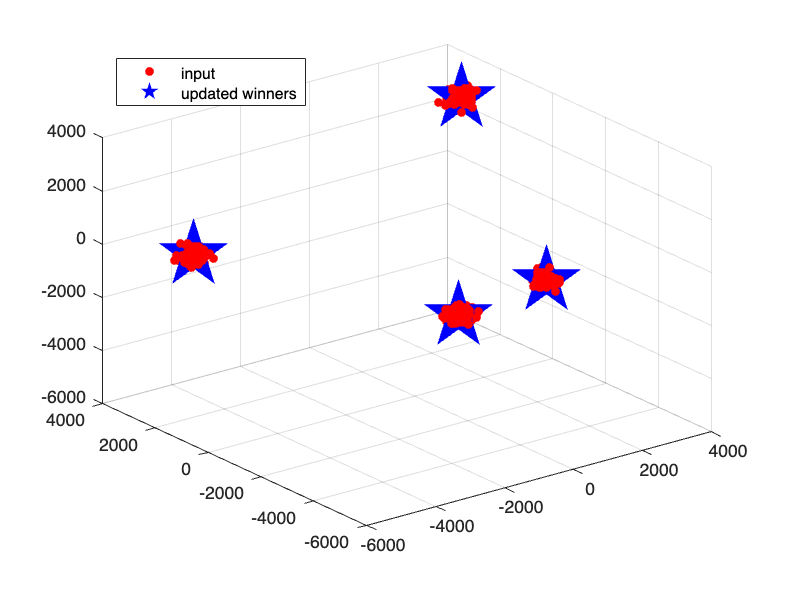


figure;
hold on
view(3)
plot3(Za1(1:len_data,1),Za1(1:len_data,2),Za1(1:len_data,3),'r.','MarkerSize',15)
plot3(Za1(end-3:end,1),Za1(end-3:end,2),Za1(end-3:end,3),'bp','MarkerFaceColor','blue','MarkerSize',40)
%plot3(Za1(end,1),Za1(end,2),Za1(end,3),'bp','MarkerFaceColor','blue','MarkerSize',10)
%title("b) after training")
legend('input','updated winners','Location','NW')
grid on
hold off